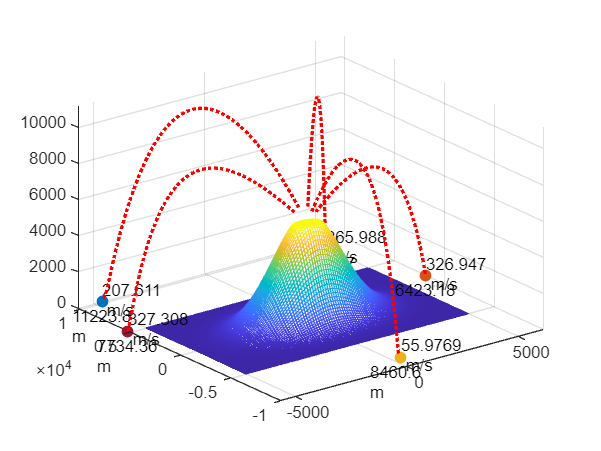

% Inicia la simulación    
rocas = 5;          % Número de rocas a simular
altura = 5393;       % Altura del volcán
%se crea el volcán
num = 100;
x = linspace(-5000, 5000, num);
y = x;
for i = 1:num
    for j = 1:num
        r = sqrt(x(i)^2 + y(j)^2); % eje xy
        z(i,j)=min(altura, altura*1.1*exp(-((.05*r/num)^2))); % eje z (vertical)
    end
end
mesh(x, y, z);         % Se crea la figura del volcán
 
g = 9.81;
densAire = 1.2;
coefArrastre = 0.47;
densRoca = 3120;
% Se definen los límites de la región del volcán
for a = 1:rocas   % Crea el número de rocas especificadas
    angulo = (30+45*rand) * pi/180;     % Ángulo aleatorio entre 20 y 90 grados // para los límites a y b en random se pone a+(b-a)*rand
    direccion = (360 *rand) * pi/180;       % Dirección con respecto del norte al que se va a disparar        
    N = 30;
    tiempoMax = 100;
   
    dt = tiempoMax/(N);
   
    velInicial = (200+100*rand); %m/s
    radio = (0.15+0.35*rand);
    masaRoca = (radio*densRoca)/(((3/4)/pi)^(1/3));
    area = pi * radio ^ 2;
    b = (densAire * coefArrastre * area);
    compX = 0;
    compY = 0;
    vr = velInicial * cos(angulo);
    velZ = velInicial * sin(angulo);
    zn = altura;
    rn = 0;
    znm1 = altura-velZ * dt-0.5 * g * dt^2; % calcular el valor anterior para poder usar Verlet
    rnm1 = -vr * dt; % calcular el valor anterior para poder usar Verlet
    trayectoria = animatedline('linewidth', 2, 'linestyle', ':','Color','r');
    hold on
   
    while zn > 0
   
% aceleración en z (vertical) = ((zn-znm1)/dt)^2 * b*0.5 / masaRoca* dt^2 - * g * dt^2
% posición en z (vertical) = ((2*zn - znm1) - ((zn-znm1)/dt)^2 * b*0.5 / masaRoca * dt^2 - 0.5 * g * dt^2
        znp1 = max(0, (2*zn - znm1) - ((zn-znm1)/dt)^2 * b*0.5 / masaRoca * dt^2 - 0.5 * g * dt^2);
   
% posición en xy = (2*rn-rnm1)-((rn-rnm1)/dt)^2*b/masaRoca*dt^2
        rnp1=(2*rn-rnm1)-((rn-rnm1)/dt)^2*b/masaRoca*dt^2;
   
        compX = rnp1 * cos(direccion);
        compY = rnp1 * sin(direccion);
   
        addpoints(trayectoria, compX, compY, znp1); % añade el nuevo punto  de la trayectoria en "animatedline"
        roca = scatter3(compX, compY, znp1, 50, 'filled');   % gráfico de dispersión
        drawnow % para que se vaya dibujando la gráfica
        if znp1 > 0
            delete(roca); % se borra la roca para que no se repita el punto en toda la trayectoria
        end
       
        hold on
        znm1 = zn;
        rnm1 = rn;
        zn = znp1;
        rn = rnp1;
    end
   
    velZ = (zn-znm1)/dt; % velocidad en z al caer (zn - z(n-1))
    vr = (rn-rnm1)/dt; % velocidad en eje xy
   
    velFinal = sqrt(velZ^2 + vr^2); %velocidad resultante
    txt = {velFinal, ' m/s'};
    t= {rn, 'm'};
    text(compX,compY, 100, txt);
    text((compX)-2500,(compY)-2500, 100, t);
end

 % Detiene la simulación